Calculation of RPM:

I*(anlge)''+Load torque= Pressure*area*moment arm*anlge'

dummy fea:

w"=-kw


N=10000

N = 10000

w=zeros(1,N)

w =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


w(1)=1

w =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


w1=zeros(1,N)

w1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


w1(1)=1

w1 =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


w2=zeros(1,N)

w2 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


dx=0.001

dx = 1.0000e-03


for n =1:N
    w2(n+1)=-2*w(n);
    w1(n+1)=w1(n)+w2(n)*dx;
    w(n+1)=w(n)+w1(n)*dx;
end
w

w =     1.0000    1.0010    1.0020    1.0030    1.0040    1.0050    1.0060    1.0070    1.0080    1.0089    1.0099    1.0109    1.0119    1.0129    1.0138    1.0148    1.0158    1.0168    1.0177    1.0187    1.0197    1.0206    1.0216    1.0225    1.0235    1.0244    1.0254    1.0263    1.0273    1.0282    1.0292    1.0301    1.0311    1.0320    1.0329    1.0339    1.0348    1.0357    1.0367    1.0376    1.0385    1.0394    1.0403    1.0413    1.0422    1.0431    1.0440    1.0449    1.0458    1.0467


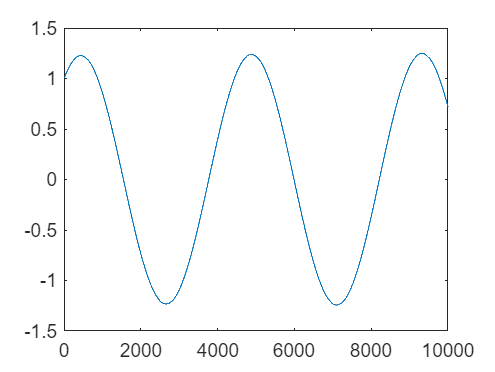

plot(w)